**EULER ALGORITHIM**

Solve y' = sin(x) - y using Euler Algorithm, with y(-2) = 3 as the initial condition

f = @(x,y) sin(x) - y;
x0 = -2;
y0 = 3;

c = exp(x0)*(y0 +0.5*(cos(x0) -sin(x0)));
fExact = @(X) c*exp(-X) + sin(X)/2 - cos(X)/2;

xf = 1; % Must be bigger than x0 (final value of x)
h = 0.01; % Domain steps (Step size)
X = x0:h:xf; % Domain value-Vector

figure(1);
plot(X, fExact(X), 'b-');
title('Numerical Solutions for $$\frac{dy}{dx} = \sin(x) - y$$','interpreter','latex');
xlabel(X);
ylabel(fExact(X));
grid on;


Numerical solutions

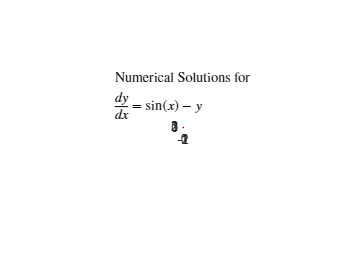

n = (xf -x0)/h +1;

y_euler = zeros(n,1); % Euler
y_euler(1) =y0;
y_midpt = zeros(n,1); % Midpoint
y_midpt(1) = y0;
y_rk4 = zeros(n,1); % Classical RungeKutta 4
y_rk4(1) = y0;


for i=2:n
    %When i = 2, this corresponds to y(k+1) = yk + h*f(xk, yk) k = 1
    xk = x0 + (i - 2)*h;
    
    %Euler (RungeKutta 1) Method
    y_euler(i,1) = y_euler(i - 1,1) + h*f(xk, y_euler(i - 1));

    % Midpoint (RungeKutta 2) Method
    L1a = f(xk,y_midpt(i-1,1));
    L2a = f(xk + h/2, y_midpt(i-1,1) + (h/2)*L1a);
    y_midpt(i,1) = y_midpt(i-1,1) + h*L2a;

    % Classical RungeKutta 4 Method
    L1b = f(xk,y_rk4(i-1,1));
    L2b = f(xk + h/2, y_rk4(i-1,1) + (h/2)*L1b);
    L3b = f(xk + h/2, y_rk4(i-1,1) + (h/2)*L2b);
    L4b = f(xk + h, y_rk4(i-1,1) + h*L3b);
    y_rk4(i,1) = y_rk4(i-1,1) + (h/6)*(L1b + 2*L2b + 2*L3b + L4b);
end

hold on;
plot(X,y_euler(:,1),'k-');
plot(X,y_midpt(:,1),'g-');
plot(X,y_rk4(:,1), 'r-');

**RUNGE-KUTTA FOR ORDER 4**

Given that y' +20y = 7e^(-0.5t); y(0) = 5, compute y(0.2) using Runge-Kutta for order 4 by taking h = 0.1.

f = @(t,y) -20*y + 7*exp(-0.5*t); %Function
t0 = 0; % Initial value of independent variable
y0 = 5; % Initial value of dependent variable
h = 0.1; % Step size
tn = 0.2; % Point at which the solution is being evaluated
n = (tn-t0)/h;
t(1) = t0; y(1) = y0;
for i=1:n
    t(i+1) = t0 + i*h;
    k1 = h*f(t(i),y(i))
    k2 = h*f(t(i) + (h/2),y(i)+(k1/2));
    k3 = h*f(t(i) + (h/2),y(i)+(k2/2));
    k4 = h*f(t(i) + h,y(i)+k3);
    y(i+1) = y(i) + (1/6)*(k1+2*k2+2*k3+k4);
    fprintf('y(%.2f) = %.4f\n',t(i+1),y(i+1))
end

k1 = -9.3000

y(0.10) = 1.8885


k1 = -3.1112

y(0.20) = 0.8406
